%WAVE SPEED AND FREQ
% actual data
freq = [5 10 15 20 25];
wavelength = [4.224 2.032 1.318 1.072 0.846];
y_err = [0.005 0.005 0.005 0.005 0.005];
x_err = [0.05 0.05 0.05 0.05 0.05];

% fitting shit
f = @(c, xdata) c./xdata;
x0 = 20;
fitted_coeff = lsqcurvefit(f, x0, freq, wavelength)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fitted_coeff = 20.8954

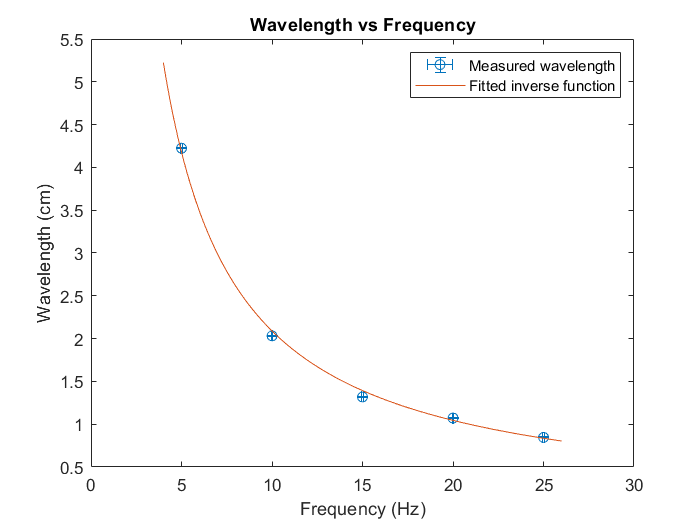


% fitted function
freq_fit = 4:0.1:26;
wavelength_fit = f(fitted_coeff, freq_fit);

errorbar(freq, wavelength, y_err, y_err, x_err, x_err, 'o');
hold on
plot(freq_fit, wavelength_fit);
title('Wavelength vs Frequency');
legend('Measured wavelength', 'Fitted inverse function');
xlabel('Frequency (Hz)');
ylabel('Wavelength (cm)');
hold off





%WAVE SPEED AND DEPTH
%actual data
d = [0.5 0.4 0.3 0.2 0.1];
v = [22.15 19.81 17.16 14.01 9.9];
y_err = [0.25 0.25 0.25 0.25 0.25];
x_err = [0.5 0.5 0.5 0.5 0.5];
%fitting
f = @(c, xdata) sqrt(c.*xdata);
x0 = 9.81;
fitted_coeff = lsqcurvefit(f, x0, d, v)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fitted_coeff = 981.2095

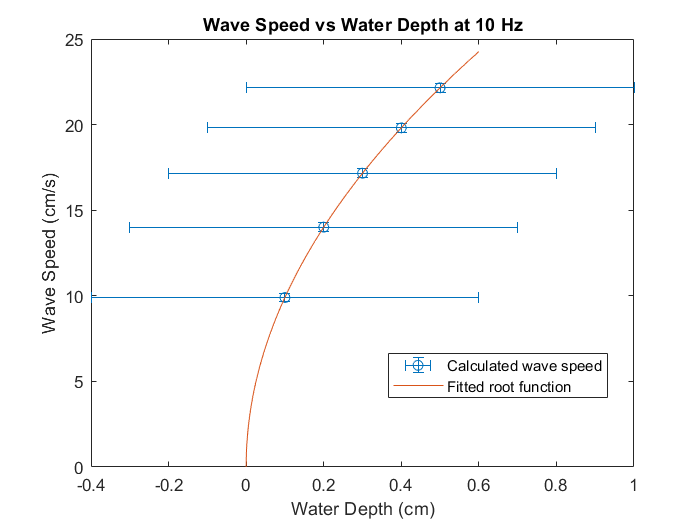

%fitted function
d_fit = 0:0.0005:0.6;
v_fit = f(fitted_coeff, d_fit);

errorbar(d, v, y_err, y_err, x_err, x_err, 'o');
hold on
plot(d_fit, v_fit);
title('Wave Speed vs Water Depth at 10 Hz');
legend('Calculated wave speed', 'Fitted root function', 'Location',"best");
xlabel('Water Depth (cm)');
ylabel('Wave Speed (cm/s)');
hold off





%DIFFRACTION

a = [2.5 3 3.5 4];
theta = [23 18 15 13];
y_err = [0.5 0.5 0.5 0.5];
x_err = [0.05 0.05 0.05 0.05];

%fitting
f = @(c, xdata) asind(c./xdata);
x0 = 1.01;
fitted_coeff = lsqcurvefit(f, x0, a, theta)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fitted_coeff = 0.9392

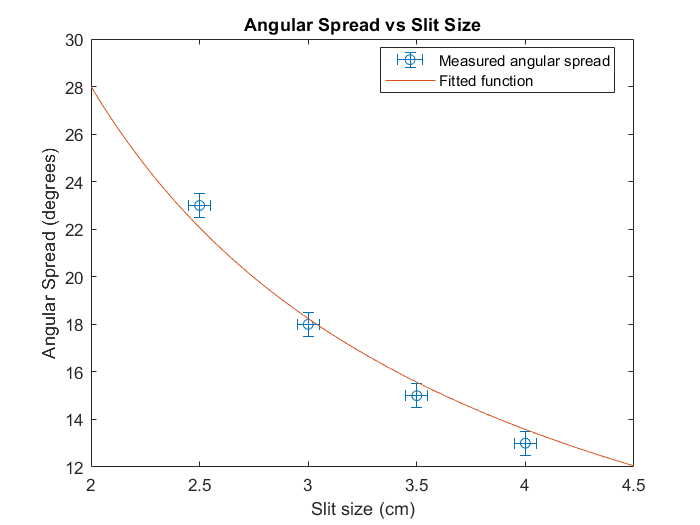

%fitted function
a_fit = 2:0.0005:4.5;
theta_fit = f(fitted_coeff, a_fit);

errorbar(a, theta, y_err, y_err, x_err, x_err, 'o');
hold on
plot(a_fit, theta_fit);
title('Angular Spread vs Slit Size');
legend('Measured angular spread', 'Fitted function', 'Location',"best");
xlabel('Slit size (cm)');
ylabel('Angular Spread (degrees)');
hold off